Auto-generated by MATLAB on 07-Jul-2021 12:28:20

## Create Array of Layers

Layers of the CNN




imd = imageDatastore(fullfile('imd'),'includeSubfolders',true ,...
    'FileExtensions','.png', ...
    'LabelSource','foldernames');
% 
% commands = categorical(["yes","no","up","down","left","right","on","off","stop","go"]);
% 
% isCommand = ismember(ads.Labels,commands);
% isUnknown = ~isCommand;
% 
% includeFraction = 0.2;
% mask = rand(numel(ads.Labels),1) < includeFraction;
% isUnknown = isUnknown & mask;
% ads.Labels(isUnknown) = categorical("unknown");
% 
% adsTrain = subset(ads,isCommand|isUnknown);


[imdsTrain,imdsTest] = splitEachLabel(imd,0.7,'randomize')

imdsTrain =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\nicol\Documents\MATLAB\REU\imd\bed\1.png';
                              'C:\Users\nicol\Documents\MATLAB\REU\imd\bed\10.png';
                              'C:\Users\nicol\Documents\MATLAB\REU\imd\bed\4.png'
                               ... and 91 more
                              }
                     Folders: {
                              'C:\Users\nicol\Documents\MATLAB\REU\imd'
                              }
                      Labels: [bed; bed; bed ... and 91 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


imdsTest =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\nicol\Documents\MATLAB\REU\imd\bed\2.png';
                              'C:\Users\nicol\Documents\MATLAB\REU\imd\bed\3.png';
                              'C:\Users\nicol\Documents\MATLAB\REU\imd\bed\6.png'
                               ... and 37 more
                              }
                     Folders: {
                              'C:\Users\nicol\Documents\MATLAB\REU\imd'
                              }
                      Labels: [bed; bed; bed ... and 37 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


imageSize = [128 128 3];
dataStore = augmentedImageDatastore(imageSize,imdsTrain)

dataStore =   augmentedImageDatastore with properties:

             NumObservations: 94
                       Files: {94×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [128 128]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0





layers = [
    imageInputLayer(imageSize)
    
    convolution2dLayer([3 3],32,"Name","conv_1","Padding","same")
    reluLayer
    maxPooling2dLayer([5 5],"Name","maxpool_1","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_2","Padding","same")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([5 5],"Name","maxpool_2","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_3","Padding","same")
    reluLayer("Name","relu_3")
    fullyConnectedLayer(12)
    softmaxLayer
    classificationLayer];

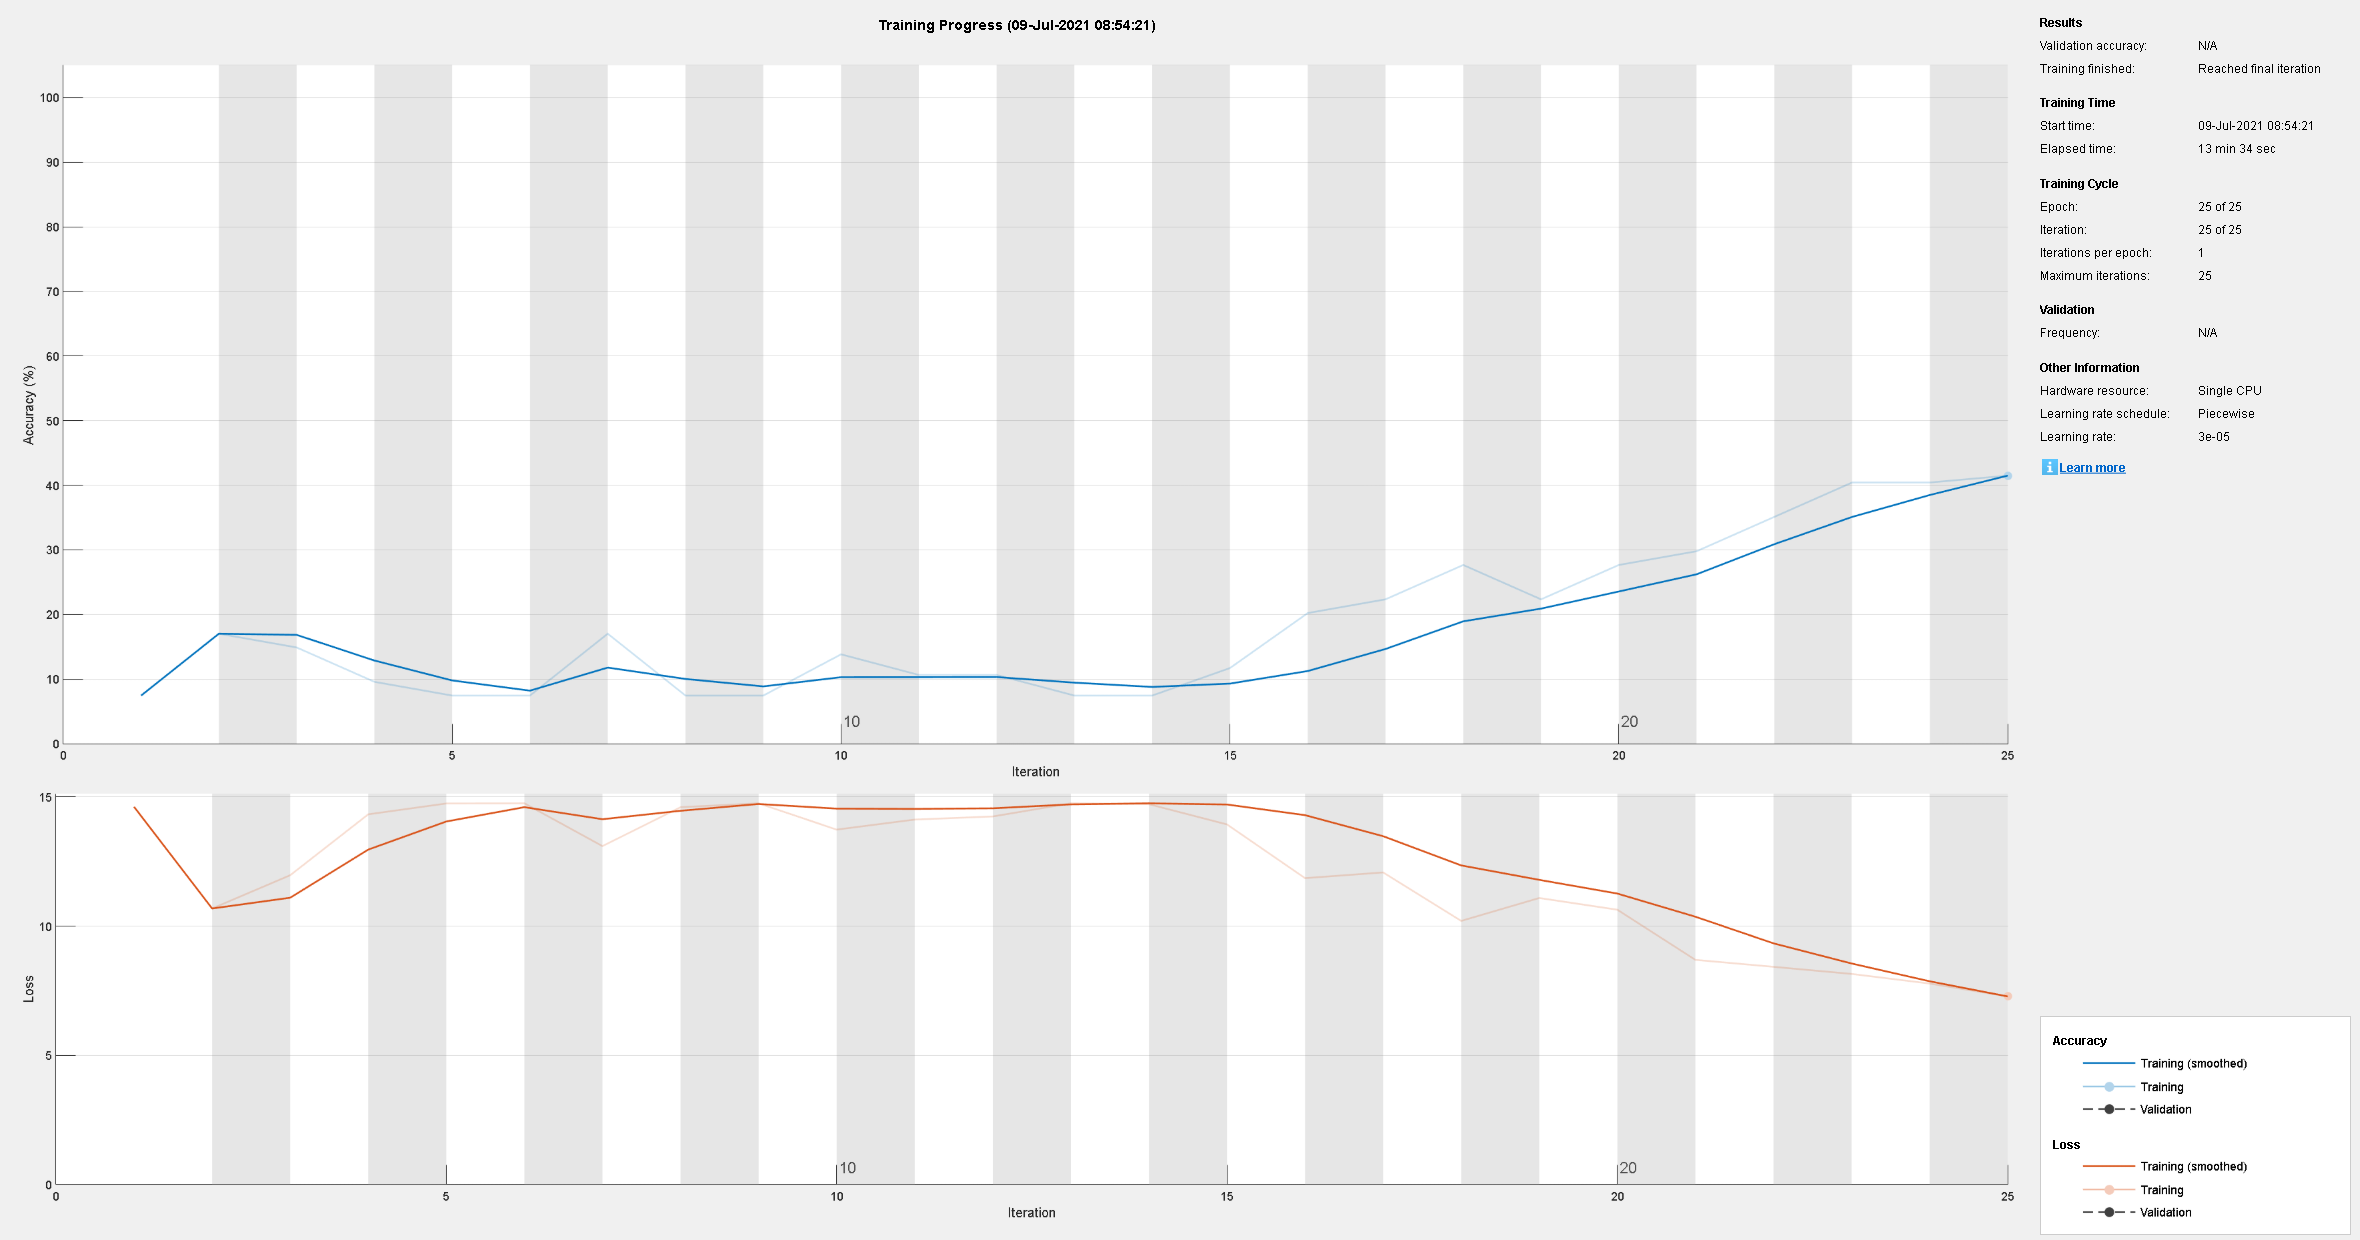

%Train 
miniBatchSize = 128;
%validationFrequency = floor(numel(YTrain)/miniBatchSize);
options = trainingOptions('adam', ...
    'InitialLearnRate',3e-4, ...
    'MaxEpochs',25, ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.1, ...
    'LearnRateDropPeriod',20);

%% Imds rpresents the the image datatstore that needs to be created
trainedNet = trainNetwork(dataStore,layers,options);

analyzeNetwork(trainedNet)

test_result = augmentedImageDatastore(imageSize,imdsTest)

test_result =   augmentedImageDatastore with properties:

             NumObservations: 40
                       Files: {40×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [128 128]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


YPred = classify(trainedNet,test_result)

YPred = 40×1 categorical array
     cat 
     cat 
     cat 
     two 
     bird 
     bird 
     bird 
     three 
     four 
     two 
     three 
     three 
     four 
     bird 
     cat 
     bird 
     three 
     three 
     three 
     two 
     two 
     bird 
     bird 
     one 
     three 
     two 
     two 
     eight 
     six 
     eight 




figure
idx = randperm(length(test_result.Files),9)

idx =      6    12     1    16    11     7    28    20    18


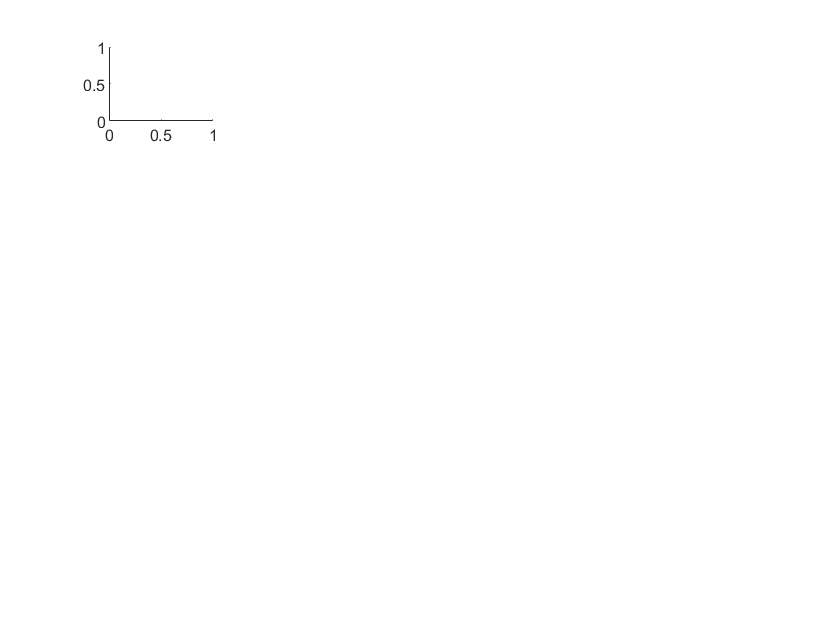

Unrecognized method, property, or field 'idx' for class 'matlab.io.datastore.ImageDatastore'.

for i=1:25
    subplot(5,5,i);
    I= readimage(imdsTest.idx(i));
    label = YPred(idx(i));
    imshow(I)
    title(char(label))
end



save trainedNet

I = imread(".\no\8.png");
I2 = imresize(I,[128 128],'nearest');
[Pred,Scores] = classify(net,I2);
scores = max(double(scores*100));
imshow(I);
title(join([string(Pred),'',scores,'%']))

% %% Evaluate Data
% 
% YValPred = classify(trainedNet,XValidation);
% validationError = mean(YValPred ~= YValidation);
% 
% YTrainPred = classify(trainedNet,XTrain);
% trainError = mean(YTrainPred ~= YTrain);
% 
% YTestPred =classify(trainedNet,XTest);
% testError = mean(YTestPred ~= YTest);
% 
% disp("Training error: " + trainError*100 + "%")
% disp("Validation error: " + validationError*100 + "%")
% disp("Test error: " +testError*100 + "%")
% 
% cm = confusionchart(YTest,YTestPred);
% cm.Title = 'Confusion Matrix for Test Data';
% cm.ColumnSummary = 'column-normalized';
% cm.RowSummary = 'row-normalized';
sortsortClasses(cm,[commands,"unknown", "background"])